# HW 3 House Modeling Code

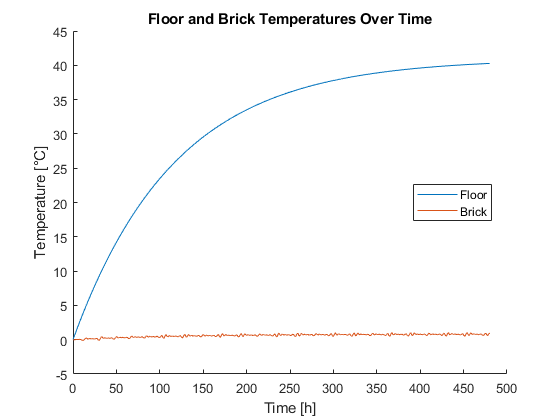

% define variables
Cf=2.0625E6; % floor heat capacity [J/K]
Cb=1.2E6; % brick heat capacity [J/K]
R1=0.2008; % thermal resistance from floor to bricks [K/W]
R2=0.004; % thermal resistance from bricks to outside air [K/W]
QdotH=200; % floor heater heat transfer rate [W]
Tf0=0+273.15; % initial floor temp [K] (0 [°C])
Tb0=0+273.15; % initial brick temp [K] (0 [°C])
Ta=0+273.15; % outside air temp (constant) [K] (0 [°C])

% solve differential equations (FUNCTION 'tempFun' AT END OF DOCUMENT)
tspan=[0,1.728E6]; % time span [s] (20 days)
T0=[Tf0,Tb0]; % pack initial floor and brick temperatures into vector
[t,Temps]=ode45(@(t,Temps) tempFun(Temps,QdotH,Cf,Cb,R1,R2,Ta),tspan,T0); % solve equation for floor temp [K]

% save and convert temperatures and time
Tf=Temps(:,1)-273.15; % floor temperatures [°C]
Tb=Temps(:,2)-273.15; % brick temperatures [°C]
tH=t./3600; % time [h]

% plot
figure()
hold on
plot(tH,Tf); % floor
plot(tH,Tb); % brick
title('Floor and Brick Temperatures Over Time')
xlabel('Time [h]'); ylabel('Temperature [°C]')
legend('Floor','Brick','Location','Best')

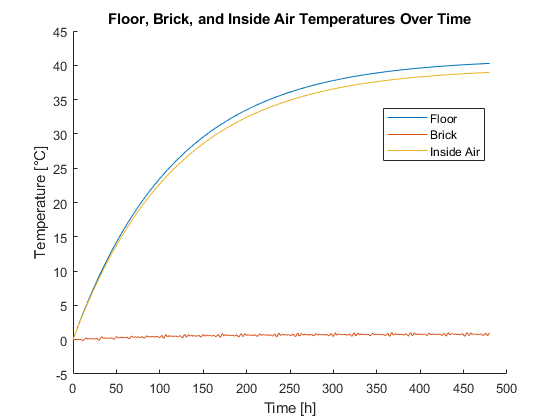

for n=1:length(tH)
    TinsideAir(n)=0.9668*Tf(n)+0.0332*Tb(n); % calculate inside air temp
end

% plot everything together
figure()
hold on
plot(tH,Tf); % floor
plot(tH,Tb); % brick
plot(tH,TinsideAir); % inside air
title('Floor, Brick, and Inside Air Temperatures Over Time')
xlabel('Time [h]'); ylabel('Temperature [°C]')
legend('Floor','Brick','Inside Air','Location','Best')

function dTdt = tempFun(Temps,QdotH,Cf,Cb,R1,R2,Ta)
    dTdt=zeros(2,1);
    dTdt(1)=(QdotH/Cf)-((Temps(1)-Temps(2))/(R1*Cf)); % floor
    dTdt(2)=((Temps(1)-Temps(2))/(R1*Cb))-((Temps(2)-Ta)/(R2*Cb)); % brick
end
